clear; close all; clc

### Cp-λ curve as a function of pitch angle β

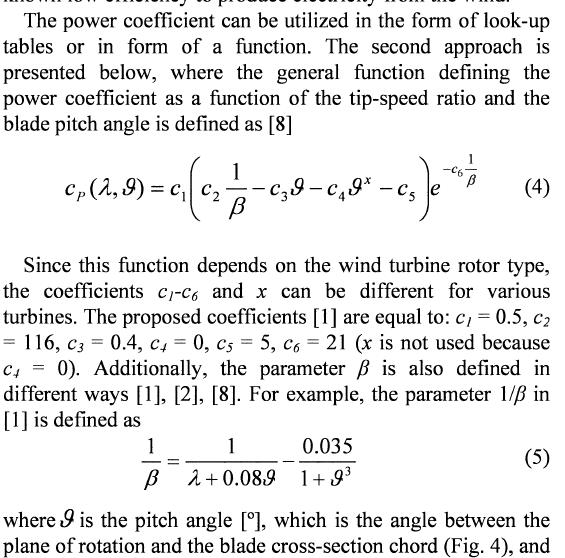

lambda = linspace(3,15,100)'; % []
beta = [0, 1, 2, 4, 6, 8]; %(0:2:10);
nb = length(beta);

for i=1:nb
%     Cp(:,i) = (0.44 - 0.0167*beta(i)) * sin(pi/2*(lambda-3)/(7.5-0.15*beta(i)))-(lambda-3)*0.00184*beta(i); % ref: Murdoch et al., Control Design and Performance Analysis of a 6 MW Wind Turbine-Generator
    b_inv = 1./(lambda+0.08*beta(i))-0.035/(1+beta(i)^3);
    Cp(:,i) = 0.6*(116*b_inv-0.4*beta(i)-5).*exp(-21.*b_inv); % ref: Rolan et al., Modeling of a Variable Speed Wind Turbine with a Permanent Magnet Synchronous Generator, ISIE 2009
    figure(1)
    hold on
    plot(lambda,Cp(:,i),'color',[(i-1)/(nb-1) 0 0])
    leg{i}=['\beta=',num2str(beta(i)),'°'];
end
grid on
xlabel('\it\lambda','fontsize',12,'fontname','times new roman')
ylabel('\itC_p','fontsize',12,'fontname','times new roman')
legend(leg)
ylim([0 0.5])


### Turbine data

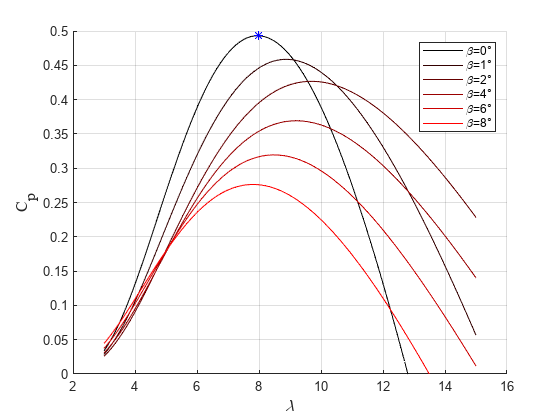

Uon = 4; % m/s cut-in wind speed
Un = 10.5; % m/s nominal wind speed 
R = 50; % m balde radius
Ad = pi*R^2; % m^2 rotor area

rho = 1.2; % kg/m^3 air density 

% nominal angular speed calculation 
[Cpmax,i_lam]=max(Cp(:,1));
lam_opt = lambda(i_lam); % optimal tip speed ratio at beta = 0
hh=plot(lam_opt,Cpmax,'*b');

hasbehavior(hh,'legend',0)
Omega = lam_opt*Un/R; % rad/s nominal angular speed

### Turbine power at constant angular speed (rated) and different wind speeds (larger than rated)

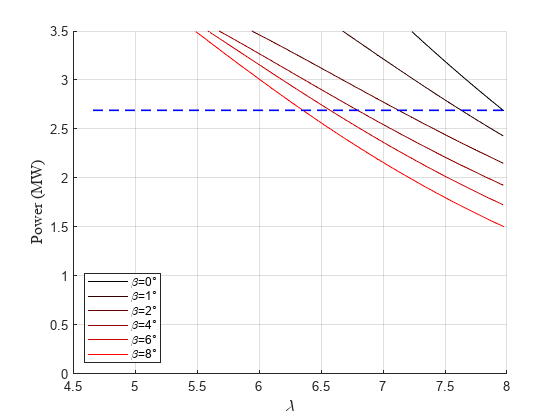

Uinf = linspace(Un,18,50)'; % m/s vector of wind speeds 
lambda_w = Omega*R./Uinf; % tip speed ratio at the different wind speeds in region III
figure(2)
clf
for i=1:nb
    P(:,i) = 1/2*rho*Ad*Uinf.^3.*interp1(lambda,Cp(:,i),lambda_w);
    figure(2)
    hold on
    plot(lambda_w,P(:,i)/1e6,'color',[(i-1)/(nb-1) 0 0])
end
legend(leg,'location','southwest')
hk=plot([lambda_w(1) lambda_w(end)],1/2*rho*Un^3*Ad*Cpmax/1e6*[1 1],'--b','linewidth',1.2);
hasbehavior(hk,'legend',0)
grid on
% xlabel('\itV_\infty\rm (m/s)','fontsize',12,'fontname','times new roman')
xlabel('\it\lambda','fontsize',12,'fontname','times new roman')
ylabel('Power (MW)','fontsize',12,'fontname','times new roman')
ylim([0 3.5])